# Basics of Translation and Rotation

## Introduction

In this section you will learn how to represent translations and rotations in a 3D space. 

After understanding the basic ideas of translation and rotations, we will combine them into homogeneous transform matrices, which will be the basis for the next tutorial. 

## Translation

Translations are represented by a vector of the same dimensions as the task space $\mathbb{R}^n \rightarrow \mathbb{R}^{n}
$

A translation along x-axis can be represented by $\left\lbrack \begin{array}{c}
\Delta \;x\\
0\\
0
\end{array}\right\rbrack$. Note that the values are w.r.t. (with respect to) the source frame. 

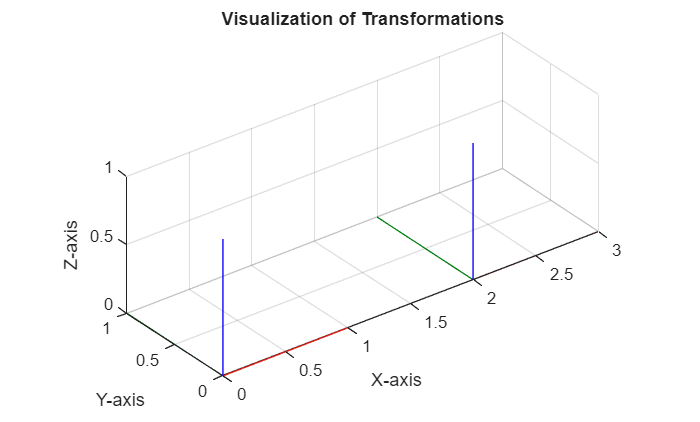

visualizeTranslation([2,0,0]);

For a translation along all axis the vector will be $\left\lbrack \begin{array}{c}
\Delta \;x\\
\Delta \;y\\
\Delta \;z
\end{array}\right\rbrack$. Note that the values are w.r.t. (with respect to) the source frame. 

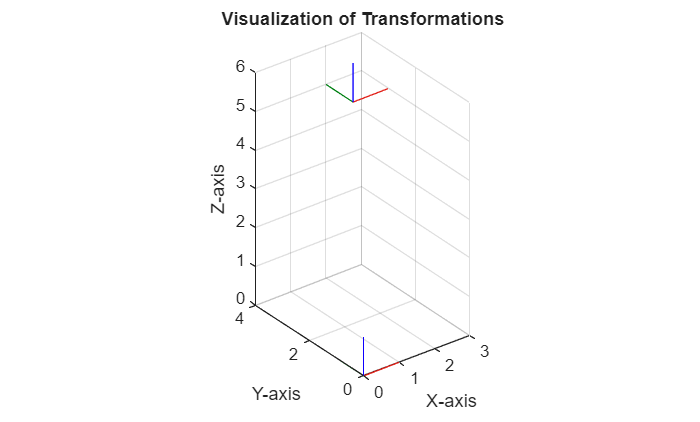

visualizeTranslation([2,3,5]);

With the following code, you can create a new frame and make its location known. The function `transl()` defines a new coordinate frame  whose origin is offset (translated) from its parent frame (starting point) the provided distances. The `TargetFrameBroadcaster` then publishes this new frame.

x_trans=0.34

x_trans = 0.3400

y_trans=0.02

y_trans = 0.0200

z_trans=0.62

z_trans = 0.6200


TargetFrameBroadcaster(transl([x_trans,y_trans,z_trans]),'my_frame')

Published static transform: world → my_frame


### Obtaining the translation vector

We can compute the translation vector by subtracting the coordinate frame origins as: 


$$\textrm{translation}\;\textrm{vector}=\textrm{target}\;\textrm{frame}-\textrm{source}\;\textrm{frame}\;$$


for the example above: 


$$\left\lbrack \begin{array}{c}
t_x \\
t_y \\
t_z 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
2\\
3\\
5
\end{array}\right\rbrack -\left\lbrack \begin{array}{c}
0\\
0\\
0
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
2\\
3\\
5
\end{array}\right\rbrack$$


## Rotations

Rotations can be represented in a few different ways. We are going to work with a matrix representation. Where $R \in  \mathbb{R}^{3x3}
$

The angle of rotation for a counter clockwise movement is positive (use right hand rule) 

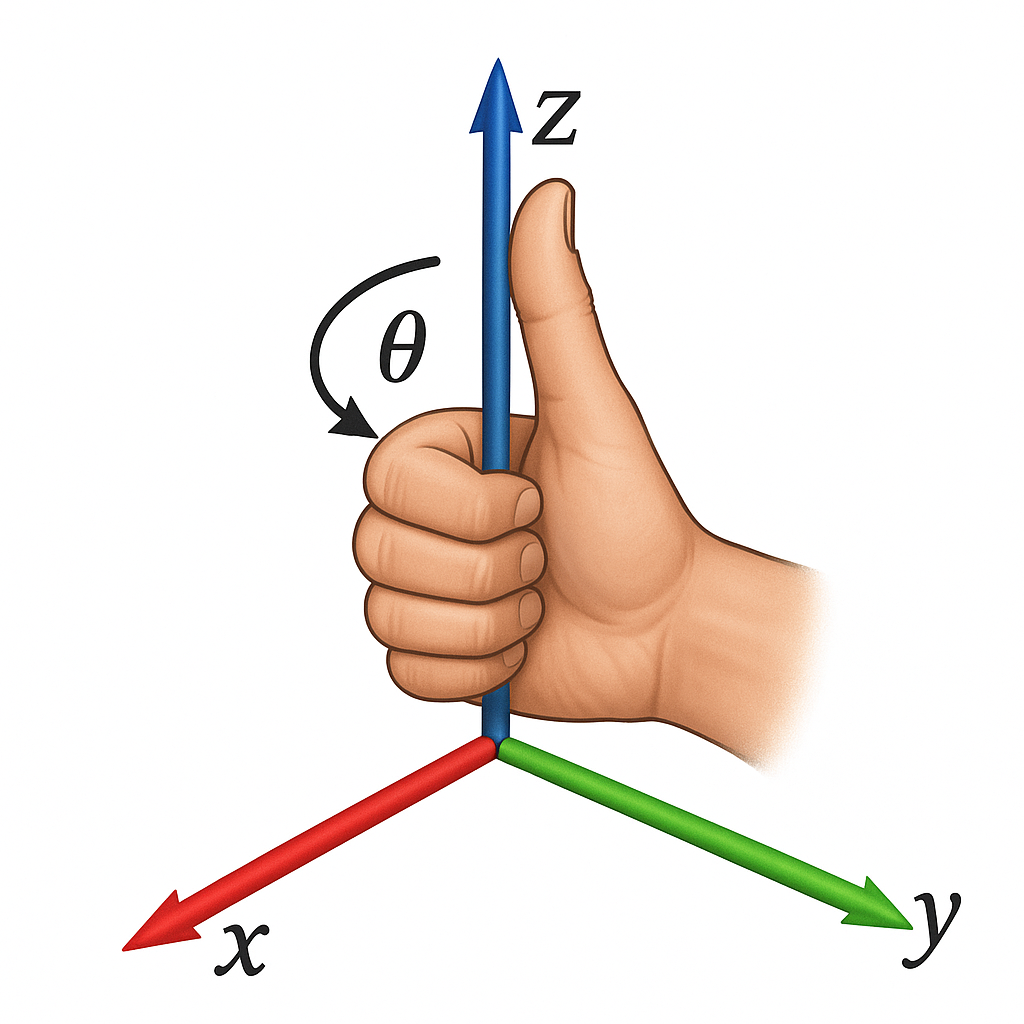

### How to define a simple rotation

We can use prebuild functions to get these matrices for a given rotation. 

syms alpha beta gamma 
Rx=rotx(alpha)

$$Rx = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & \cos\left(\alpha \right) & -\sin\left(\alpha \right)\\ 0 & \sin\left(\alpha \right) & \cos\left(\alpha \right) \end{array}\right)$$

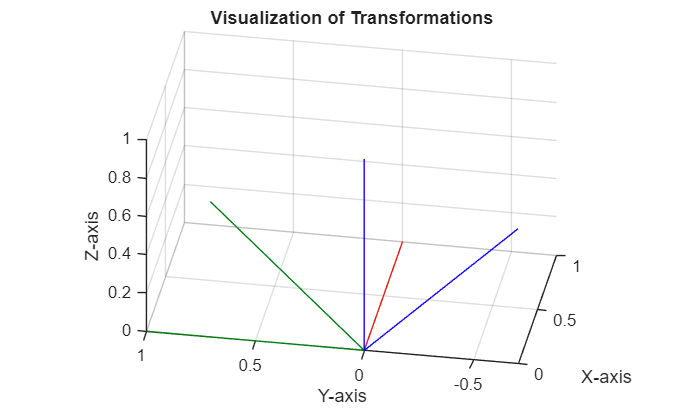

visualizeRotation(double(subs(Rx, alpha, pi/4)),'x') %alpha = 45° = pi/4

Ry=roty(beta)

$$Ry = \left(\begin{array}{ccc} \cos\left(\beta \right) & 0 & \sin\left(\beta \right)\\ 0 & 1 & 0\\ -\sin\left(\beta \right) & 0 & \cos\left(\beta \right) \end{array}\right)$$

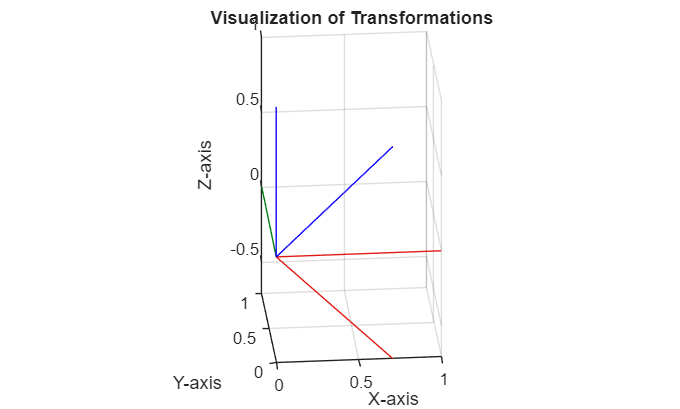

visualizeRotation(double(subs(Ry, beta, pi/4)),'y') %beta = 45° = pi/4

Rz=rotz(gamma)

$$Rz = \left(\begin{array}{ccc} \cos\left(\gamma \right) & -\sin\left(\gamma \right) & 0\\ \sin\left(\gamma \right) & \cos\left(\gamma \right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

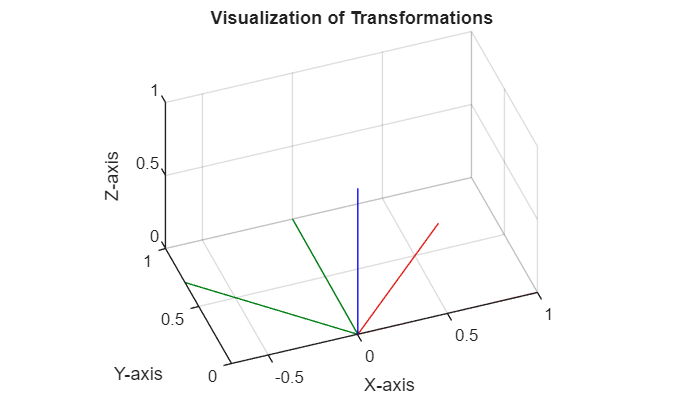

visualizeRotation(double(subs(Rz, gamma, pi/4)), 'z') %gamma = 45° = pi/4

Multiplying these rotations with one another, gives us complex rotations in 3D space. 

The order of individual rotations is important for the final matrix, as each consecutive rotation relates to the new coordinate frame. 

clear all; 

### Rotation Notation

In robotics we often need to switch between different ways of describing a 3-D rotation. Instead of giving a full matrix, we can represent any rotation by a set of angles and a specific order. 

The main representations are:

### **Euler Angles (ZYZ)**

Also called **moving-axis** Euler angles (ϕ,  θ,  ψ), as the rotations revolve around the new updated axis:

- Rotate by ϕ about the original z.

- Rotate by θ about the new y.

- Rotate by ψ about the newest z.

syms phi theta psi
R = rotz(phi) * roty(theta) * rotz(psi)

We can also use the build-in functions for numerical values:

Angles = [phi, theta, psi]; 
Angles_num = double(subs(Angles, [phi, theta, psi], [pi/2, pi/3, pi/4]));

$$R = \left(\begin{array}{ccc} \cos\left(\varphi \right)\,\cos\left(\psi \right)\,\cos\left(\theta \right)-\sin\left(\varphi \right)\,\sin\left(\psi \right) & -\cos\left(\psi \right)\,\sin\left(\varphi \right)-\cos\left(\varphi \right)\,\cos\left(\theta \right)\,\sin\left(\psi \right) & \cos\left(\varphi \right)\,\sin\left(\theta \right)\\ \cos\left(\varphi \right)\,\sin\left(\psi \right)+\cos\left(\psi \right)\,\cos\left(\theta \right)\,\sin\left(\varphi \right) & \cos\left(\varphi \right)\,\cos\left(\psi \right)-\cos\left(\theta \right)\,\sin\left(\varphi \right)\,\sin\left(\psi \right) & \sin\left(\varphi \right)\,\sin\left(\theta \right)\\ -\cos\left(\psi \right)\,\sin\left(\theta \right) & \sin\left(\psi \right)\,\sin\left(\theta \right) & \cos\left(\theta \right) \end{array}\right)$$

R_func = eul2rotm(Angles_num, "ZYZ")

#### Compute Euler Angles from Rotation Matrix

For the inverse of this problem (computing the angles from a rotation matrix), we can solve it analytically: 


$$R=\left\lbrack \begin{array}{ccc}
r_{11}  & r_{12}  & r_{13} \\
r_{21}  & r_{22}  & r_{23} \\
r_{31}  & r_{32}  & r_{33} 
\end{array}\right\rbrack$$



$$\phi =\textrm{atan2}\left(r_{23} ,\;r_{13} \right)=\textrm{atan2}\left(-r_{23} ,\;-r_{13} \right)$$



$$\theta =\textrm{atan2}\left(\sqrt{\;r_{13}^2 +r_{23}^2 },r_{33} \right)$$



$$\psi =\textrm{atan2}\left(r_{32} ,\;{-r}_{31} \right)=\textrm{atan2}\left(-r_{32} ,\;r_{31} \right)$$


We can also use the build-in function rotm2eul(R, sequence) or tform2eul(T, sequence) for homogeneous transforms. 

For the example values: 


$$\phi = \ 0 \\
\theta = \frac{\pi}{2} \\
\psi = \frac{\pi}{3}
$$


substituting $\phi, \ \theta \ and \ \psi $: 

R_subs = double(subs(R, [phi, theta, psi], [0, pi/2, pi/3]));  
ZYZ_angles = rotm2eul(R_subs, "ZYZ")

*Note that a same rotation matrix can be obtained with different combination of euler angles. This is why, the obtained angles are not equal to the ones computed. *

clear all; 

R_func =    -0.7071   -0.7071    0.0000
    0.3536   -0.3536    0.8660
   -0.6124    0.6124    0.5000


### Euler Angles (RPY/ZYX)

Also called **roll-pitch-yaw** (fixed axes) or ZYX Euler angles (roll,  pitch,  yaw). Here the angles correspond to a fixed reference frame where: 

$\theta_r \ = \ Roll \ \ \Rightarrow$ Rotation around X-axis

$\theta_p \ = \ Pitch \ \Rightarrow$ Rotation around Y-axis

$\theta_y \ = \ Yaw \ \ \Rightarrow$ Rotation around Z-axis

This is achieved by applying the angles in the following order:

- Rotate by $\theta_y$ about the original Z.

- Rotate by $\theta_p$ about the original Y.

- Rotate by $\theta_r$ about the original X.

syms roll pitch yaw 
R = rotz(yaw) * roty(pitch) * rotx(roll)

ZYZ_angles =    -3.1416   -1.5708   -2.0944


We can also use the build-in functions for numerical values:

RPY = [roll, pitch, yaw];
RPY_num = double(subs(RPY, [roll, pitch, yaw], [pi/2, pi/3, pi]));
R_num = eul2rotm(RPY_num, "ZYX")

#### Compute RPY Angles from Rotation Matrix

For the inverse of this problem (computing the angles from a rotation matrix), we can solve it analytically: 


$$R=\left\lbrack \begin{array}{ccc}
r_{11}  & r_{12}  & r_{13} \\
r_{21}  & r_{22}  & r_{23} \\
r_{31}  & r_{32}  & r_{33} 
\end{array}\right\rbrack$$



$$\theta_r =\textrm{atan2}\left(r_{21} ,\;r_{11} \right)=\textrm{atan2}\left(-r_{21} ,\;-r_{11} \right)$$



$$\theta_p =\textrm{atan2}\left(-r_{31} ,\;\sqrt{\;r_{32}^2 +r_{33}^2 }\right)=\textrm{atan2}\left(-r_{31} ,\;-\sqrt{\;r_{32}^2 +r_{33}^2 }\right)$$



$$\theta_y =\textrm{atan2}\left(r_{32} ,\;r_{33} \right)=\textrm{atan2}\left(-r_{32} ,-r_{33} \right)$$


We can also use the build-in function rotm2eul(R, sequence) or tform2eul(T,sequence) for homogeneous transforms.  

For the example values: 


$$\theta_r= \ 0 \\
\theta_p= \frac{\pi}{2} \\
\theta_y= \frac{\pi}{3}
$$


substituting $\phi, \ \theta \ and \ \psi $: 

R_subs = double(subs(R, [roll, pitch, yaw], [0, pi/2, pi/3])); 
RPY_angles = rotm2eul(R_subs, "ZYX")

$$R = \left(\begin{array}{ccc} \cos\left(\mathrm{pitch}\right)\,\cos\left(\mathrm{yaw}\right) & \cos\left(\mathrm{yaw}\right)\,\sin\left(\mathrm{pitch}\right)\,\sin\left(\mathrm{roll}\right)-\cos\left(\mathrm{roll}\right)\,\sin\left(\mathrm{yaw}\right) & \sin\left(\mathrm{roll}\right)\,\sin\left(\mathrm{yaw}\right)+\cos\left(\mathrm{roll}\right)\,\cos\left(\mathrm{yaw}\right)\,\sin\left(\mathrm{pitch}\right)\\ \cos\left(\mathrm{pitch}\right)\,\sin\left(\mathrm{yaw}\right) & \cos\left(\mathrm{roll}\right)\,\cos\left(\mathrm{yaw}\right)+\sin\left(\mathrm{pitch}\right)\,\sin\left(\mathrm{roll}\right)\,\sin\left(\mathrm{yaw}\right) & \cos\left(\mathrm{roll}\right)\,\sin\left(\mathrm{pitch}\right)\,\sin\left(\mathrm{yaw}\right)-\cos\left(\mathrm{yaw}\right)\,\sin\left(\mathrm{roll}\right)\\ -\sin\left(\mathrm{pitch}\right) & \cos\left(\mathrm{pitch}\right)\,\sin\left(\mathrm{roll}\right) & \cos\left(\mathrm{pitch}\right)\,\cos\left(\mathrm{roll}\right) \end{array}\right)$$

*Note that a same rotation matrix can be obtained with different combination of euler angles. This is why, the obtained angles are not equal to the ones computed. *

clear all; 

### Quaternions

Quaternions provide a four-parameter, singularity-free way to encode any 3D rotation.

A unit quaternion is represented by $q=\left\lbrack w\;,x,y,z\right\rbrack$

with 


$$\begin{array}{l}
w=\cos \left(\frac{\theta }{2}\right)\\
x=\sin \left(\frac{\theta }{2}\right)\cdot u_x \\
y=\sin \left(\frac{\theta }{2}\right)\cdot u_y \\
z=\sin \left(\frac{\theta }{2}\right)\cdot u_z 
\end{array}$$


The Rotation matrix can be constructed as: 


$$R=\left\lbrack \begin{array}{ccc}
2\cdot \;\left(w^2 +x^2 \right)-1 & \;\;\;\;\;2\cdot \;\left(x\cdot \;y-w\cdot z\right) & \;\;\;\;\;2\cdot \;\left(x\cdot z-w\cdot y\right)\\
2\cdot \;\left(x\cdot \;y-w\cdot z\right) & \;\;\;\;\;2\cdot \;\left(w^2 +y^2 \right)-1 & \;\;\;\;\;2\cdot \;\left(y\cdot z-w\cdot x\right)\\
2\cdot \;\left(x\cdot z-w\cdot y\right) & \;\;\;\;\;2\cdot \;\left(y\cdot z-w\cdot x\right) & \;\;\;\;\;2\cdot \;\left(w^2 +z^2 \right)-1
\end{array}\right\rbrack$$


We can use build-in functions to compute the Rotation Matrix from Quaternions. For example a quaternion describing a rotation around x with 90° would be: 


$$\theta =\frac{\pi }{2}=90\degree$$



$$\vec{\;u} =\vec{\;x} =\left\lbrack \begin{array}{c}
1\\
0\\
0
\end{array}\right\rbrack$$


q = [cos(pi/4)	1*sin(pi/4)	0	0];
RotxMat=rotx(pi/2)

R_num =     0.0000    1.0000    0.0000
    0.5000    0.0000   -0.8660
   -0.8660    0.0000   -0.5000


R = quat2rotm(q)

#### Compute Quaternions from Rotation Matrix

For the inverse of this problem (computing the angles from a rotation matrix), we can solve it analytically: 


$$R=\left\lbrack \begin{array}{ccc}
r_{11}  & r_{12}  & r_{13} \\
r_{21}  & r_{22}  & r_{23} \\
r_{31}  & r_{32}  & r_{33} 
\end{array}\right\rbrack$$



$$w=\frac{1}{2}\cdot \sqrt{\;r_{11} +r_{22} +r_{33} +1}$$



$$x=\frac{r_{32} -r_{23} }{4\cdot \;w}$$



$$y=\frac{r_{13} -r_{31} }{4\cdot \;w}$$



$$z=\frac{r_{21} -r_{12} }{4\cdot \;w}$$


#### **Special Cases**

The primary issue is encountered when the Trace of the matrix (sum of diagonal elements) is less or equal than 0. If so, the computations need to be adjusted, otherwise you might end up with imaginary numbers for w or with a division by 0 while calculating  x/y/z. 

To avoid this, you must first identify the greatest diagonal element and then calculate a scaling factor (S)


$${\mathit{\mathbf{r}}}_{11} >{\mathit{\mathbf{r}}}_{22} \;\;\textrm{and}\;{\mathit{\mathbf{r}}}_{11} >{\mathit{\mathbf{r}}}_{33}$$



$$S=2\cdot \sqrt{1+\;r_{11} -r_{22} -r_{33} }=4\cdot x$$
 


$$w=\frac{r_{32} -r_{23} }{S}$$



$$x=\frac{1}{2}\cdot \sqrt{1+\;r_{11} -r_{22} -r_{33} }=0\ldotp 25\cdot S$$



$$y=\frac{r_{12} +r_{21} }{S}\;\;$$



$$z=\frac{r_{13} +r_{31} }{S}\;\;$$



$${\mathit{\mathbf{r}}}_{22} >{\mathit{\mathbf{r}}}_{11} \;\;\textrm{and}\;{\mathit{\mathbf{r}}}_{22} >{\mathit{\mathbf{r}}}_{33}$$



$$S=2\cdot \sqrt{1+\;r_{22} -r_{11} -r_{33} }=4\cdot y$$
 


$$w=\frac{r_{13} -r_{31} }{S}$$



$$x=\frac{r_{12} +r_{21} }{S}$$



$$y=0\ldotp 25\cdot S$$



$$z=\frac{r_{23} +r_{32} }{S}\;\;$$



$${\mathit{\mathbf{r}}}_{33} >{\mathit{\mathbf{r}}}_{11} \;\;\textrm{and}\;{\mathit{\mathbf{r}}}_{33} >{\mathit{\mathbf{r}}}_{22}$$



$$S=2\cdot \sqrt{1+\;r_{33} -r_{11} -r_{22} }=4\cdot z$$
 


$$w=\frac{r_{21} -r_{12} }{S}$$



$$x=\frac{r_{13} +r_{31} }{S}$$



$$y=\frac{r_{23} +r_{32} }{S}$$



$$z=0\ldotp 25\cdot S\;\;$$


#### Toolbox implementation

We can also use the build-in function rotm2quat(R) to compute the Quaternions from a rotation matrix

q=rotm2quat(R)
clear all; 

RPY_angles =          0    1.5708   -1.0472


## Homogeneous Transformations

Homogeneous Transformations allow us to encode a translation and rotation in a single matrix of the form: 


$$T=\left\lbrack \begin{array}{ccccc}
 &  &  & | & \\
 & R\in {\mathbb{R}}^{3\textrm{x3}}  &  & | & t\in {\mathbb{R}}^{3\textrm{x1}} \\
 &  &  & | & \\
-- & -- & -- & + & --\\
0 & 0 & 0 & | & 1
\end{array}\right\rbrack =\left\lbrack \begin{array}{cccc}
r_{11}  & r_{12}  & r_{13}  & \Delta \;x\\
r_{21}  & r_{22}  & r_{23}  & \Delta \;y\\
r_{13}  & r_{32}  & r_{33}  & \Delta \;z\\
0 & 0 & 0 & 1
\end{array}\right\rbrack$$


#### Matlab implementation

Here are some ways to create them:

syms theta dx dy dz real
T = eye(4); %create a 4x4 identity matrix
T=sym(T) %Convert matrix to symbolic 
T(1:3,1:3) = rotx(theta) %fill rotation part 
translation_vector = [dx, dy, dz]' 
T(1:3,4) = translation_vector %fill translation part

We can also use functions to create homogeneous transform matrices:

T_Rotx = trotx(theta)
T_Roty = troty(theta)

RotxMat =     1.0000         0         0
         0    0.0000   -1.0000
         0    1.0000    0.0000


T_Rotz = trotz(theta)

R =     1.0000         0         0
         0    0.0000   -1.0000
         0    1.0000    0.0000


T_trans = transl([dx,dy,dz])
T_combined = T_trans * T_Rotx %note the order of multiplicands 

q =     0.7071    0.7071         0         0


$$T = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$T = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & \cos\left(\theta \right) & -\sin\left(\theta \right) & 0\\ 0 & \sin\left(\theta \right) & \cos\left(\theta \right) & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$translation\_vector = \left(\begin{array}{c} \mathrm{dx}\\ \mathrm{dy}\\ \mathrm{dz} \end{array}\right)$$

$$T = \left(\begin{array}{cccc} 1 & 0 & 0 & \mathrm{dx}\\ 0 & \cos\left(\theta \right) & -\sin\left(\theta \right) & \mathrm{dy}\\ 0 & \sin\left(\theta \right) & \cos\left(\theta \right) & \mathrm{dz}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$T\_Rotx = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & \cos\left(\theta \right) & -\sin\left(\theta \right) & 0\\ 0 & \sin\left(\theta \right) & \cos\left(\theta \right) & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$T\_Roty = \left(\begin{array}{cccc} \cos\left(\theta \right) & 0 & \sin\left(\theta \right) & 0\\ 0 & 1 & 0 & 0\\ -\sin\left(\theta \right) & 0 & \cos\left(\theta \right) & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$T\_Rotz = \left(\begin{array}{cccc} \cos\left(\theta \right) & -\sin\left(\theta \right) & 0 & 0\\ \sin\left(\theta \right) & \cos\left(\theta \right) & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$T\_trans = \left(\begin{array}{cccc} 1 & 0 & 0 & \mathrm{dx}\\ 0 & 1 & 0 & \mathrm{dy}\\ 0 & 0 & 1 & \mathrm{dz}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$T\_combined = \left(\begin{array}{cccc} 1 & 0 & 0 & \mathrm{dx}\\ 0 & \cos\left(\theta \right) & -\sin\left(\theta \right) & \mathrm{dy}\\ 0 & \sin\left(\theta \right) & \cos\left(\theta \right) & \mathrm{dz}\\ 0 & 0 & 0 & 1 \end{array}\right)$$